clear

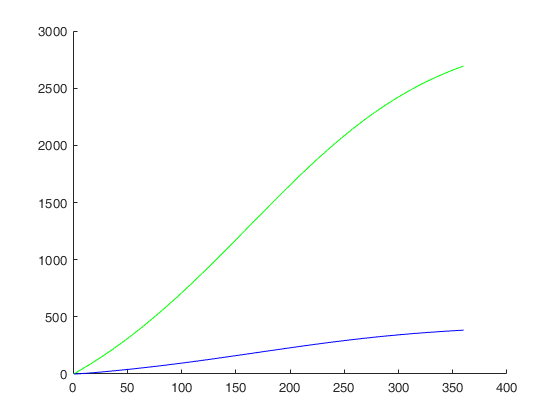

Rate        = 0.8;
Balance     = 0.8;
Invest_N    = 0.75;
Invest_V    = 1-Invest_N;
a_1         = 0.4;
a_2         = 0.15;
a_3         = 0.05;
b_1         = 28;
b_2         = 0.01;
b_3         = 1;
NVratio_max = 1/4;
NVratio_best= 1/7;
NVratio_min = 1/12;
V_boundary  = 30;
%NVratio_max 1/7
%NVratio_min 1/12
maxn        = 360;
N_s         = zeros(maxn,1);
V_s         = zeros(maxn,1);
for n = 1:maxn-1
    if N_s(n)/V_s(n) < NVratio_best % 15cars 1charger
        interinfluence = (V_s(n)*NVratio_best - N_s(n))/(N_s(n)+eps); %1.25 - 1 > 0
    elseif N_s(n)/V_s(n) > NVratio_max %5cars 1charger
        interinfluence = -(N_s(n) - V_s(n)*NVratio_max)/(N_s(n)+eps); %1-5/7 > 0
    else
        interinfluence = 0;
    end
    if interinfluence > 10
        interinfluence = 10;
    end
    praise          = b_2*(V_s(n)-V_boundary);
    if praise < 0
        praise = 0;
    end
    N_s(n+1)        = (a_1*Invest_N + a_2*N_s(n)*interinfluence) + N_s(n);
    V_s(n+1)        = (b_1*Invest_V - a_3*V_s(n)*interinfluence + praise - b_3*abs(Rate - Balance)) * (1-V_s(n)/3000) + V_s(n);
    if N_s(n+1) < 0
        N_s(n+1) = 0;
    end
    if V_s(n+1) < 0
        V_s(n+1) = 0;
    end
end
hold on;
plot(V_s,'-g')
plot(N_s,'-b')
hold off;

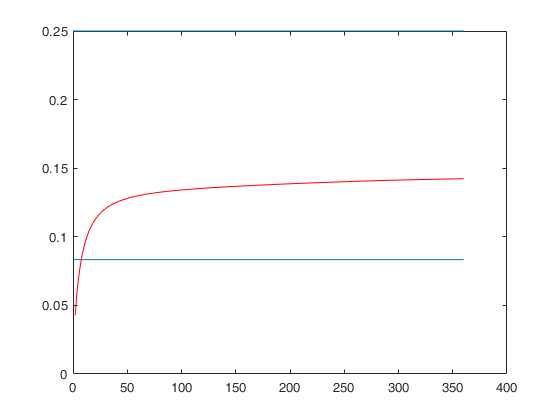

plot(N_s./V_s,'-r')
hold on;
line([0 maxn],[NVratio_max NVratio_max]);
line([0 maxn],[NVratio_min NVratio_min])

%axis([0 maxn 0 3])